## Naïve Bayes Analysis part 2

Analysis & Hyperparameter Search on the dataset here uses the standardised dataset with fewer features.

### This section clears the workspace, loads the dataset

The dataset used is the standardised dataset, the features previously identified as not useful are removed.

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
%[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
%X = table2array(X);
%Y = table2array(Y);
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1



## Run Hyperparameter Search

### Using Default 'normal' Distribution Name

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getDefaultTestHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesDefaultSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: -1.0000 
	Smoother Type: N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A 
	DistName: 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 1098 entries out of 3200. 34.3125 pct
	Training loss: 0.34. Test Loss: 0.34
	Precision: 0.6591 Recall: 0.6690 Accuracy: 0.6569 F1: 0.6640
Test run HoldRunCount: 1 of 2,Width: -1.0000 
	Smoother Type: N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A 
	DistName: 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 23.7188

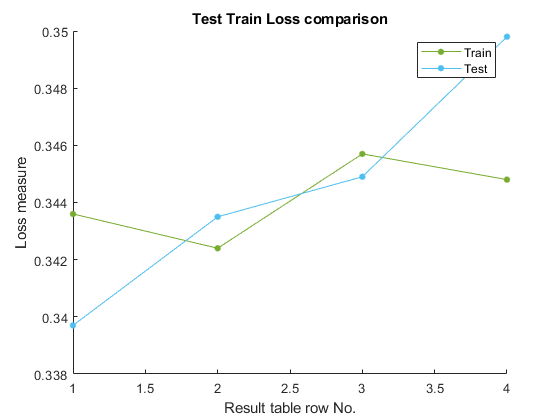

results.plotLossTestTrainComparison("Test Train Loss comparison")

### Kernel Distribution Names (uses normal distribution for each feature)

#### Triangle Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernelTriangleSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesTriangleSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 768 entries out of 3200. 24.0000 pct
	Training loss: 0.23. Test Loss: 0.24
	Precision: 0.7615 Recall: 0.7729 Accuracy: 0.7600 F1: 0.7672
Test run HoldRunCount: 1 of 2,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 810 entries out of 3200. 25.3125 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7461 Recall: 0.7580 Accuracy: 0.7469 F1: 0.7520
Test run HoldRunCount: 2 of 2,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 789 entries out of 3200. 24.6563 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7528 Recall: 0.7683 Accuracy: 0.7534 F1: 0.7605
Test run HoldRunCount: 1 of 5,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 825 entries out of 3200. 25.7813 pct
	Training loss: 0.23. Test Loss: 0.26
	Precision: 0.7414 Recall: 0.7542 Accuracy: 0.7422 F1: 0.7477
Test run HoldRunCount: 2 of 5,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 784 entries out of 3200. 24.5000 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7540 Recall: 0.7689 Accuracy: 0.7550 F1: 0.7613
Test run HoldRunCount: 3 of 5,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 784 entries out of 3200. 24.5000 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7541 Recall: 0.7698 Accuracy: 0.7550 F1: 0.7619
Test run HoldRunCount: 4 of 5,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 759 entries out of 3200. 23.7188 pct
	Training loss: 0.24. Test Loss: 0.24
	Precision: 0.7619 Recall: 0.7756 Accuracy: 0.7628 F1: 0.7687
Test run HoldRunCount: 5 of 5,Width: 0.1000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 806 entries out of 3200. 25.1875 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7450 Recall: 0.7585 Accuracy: 0.7481 F1: 0.7517
Test run HoldRunCount: 1 of 1,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 821 entries out of 3200. 25.6563 pct
	Training loss: 0.23. Test Loss: 0.26
	Precision: 0.7434 Recall: 0.7593 Accuracy: 0.7434 F1: 0.7513
Test run HoldRunCount: 1 of 2,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 795 entries out of 3200. 24.8438 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7502 Recall: 0.7638 Accuracy: 0.7516 F1: 0.7569
Test run HoldRunCount: 2 of 2,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 812 entries out of 3200. 25.3750 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7480 Recall: 0.7612 Accuracy: 0.7462 F1: 0.7545
Test run HoldRunCount: 1 of 5,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 791 entries out of 3200. 24.7188 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7513 Recall: 0.7658 Accuracy: 0.7528 F1: 0.7585
Test run HoldRunCount: 2 of 5,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 790 entries out of 3200. 24.6875 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7511 Recall: 0.7661 Accuracy: 0.7531 F1: 0.7585
Test run HoldRunCount: 3 of 5,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 844 entries out of 3200. 26.3750 pct
	Training loss: 0.23. Test Loss: 0.26
	Precision: 0.7359 Recall: 0.7554 Accuracy: 0.7362 F1: 0.7455
Test run HoldRunCount: 4 of 5,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 819 entries out of 3200. 25.5938 pct
	Training loss: 0.23. Test Loss: 0.26
	Precision: 0.7426 Recall: 0.7597 Accuracy: 0.7441 F1: 0.7511
Test run HoldRunCount: 5 of 5,Width: 0.0984 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 812 entries out of 3200. 25.3750 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7470 Recall: 0.7617 Accuracy: 0.7462 F1: 0.7543
Test run HoldRunCount: 1 of 1,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 779 entries out of 3200. 24.3438 pct
	Training loss: 0.24. Test Loss: 0.24
	Precision: 0.7565 Recall: 0.7714 Accuracy: 0.7566 F1: 0.7639
Test run HoldRunCount: 1 of 2,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 799 entries out of 3200. 24.9688 pct
	Training loss: 0.24. Test Loss: 0.25
	Precision: 0.7491 Recall: 0.7618 Accuracy: 0.7503 F1: 0.7554
Test run HoldRunCount: 2 of 2,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 817 entries out of 3200. 25.5313 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7455 Recall: 0.7598 Accuracy: 0.7447 F1: 0.7526
Test run HoldRunCount: 1 of 5,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 793 entries out of 3200. 24.7813 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7535 Recall: 0.7712 Accuracy: 0.7522 F1: 0.7623
Test run HoldRunCount: 2 of 5,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 787 entries out of 3200. 24.5938 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7543 Recall: 0.7672 Accuracy: 0.7541 F1: 0.7607
Test run HoldRunCount: 3 of 5,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 762 entries out of 3200. 23.8125 pct
	Training loss: 0.24. Test Loss: 0.24
	Precision: 0.7608 Recall: 0.7771 Accuracy: 0.7619 F1: 0.7689
Test run HoldRunCount: 4 of 5,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 813 entries out of 3200. 25.4063 pct
	Training loss: 0.23. Test Loss: 0.26
	Precision: 0.7443 Recall: 0.7635 Accuracy: 0.7459 F1: 0.7538
Test run HoldRunCount: 5 of 5,Width: 0.0932 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 821 entries out of 3200. 25.6563 pct
	Training loss: 0.23. Test Loss: 0.26
	Precision: 0.7437 Recall: 0.7562 Accuracy: 0.7434 F1: 0.7499
Test run HoldRunCount: 1 of 1,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 825 entries out of 3200. 25.7813 pct
	Training loss: 0.24. Test Loss: 0.26
	Precision: 0.7403 Recall: 0.7555 Accuracy: 0.7422 F1: 0.7478
Test run HoldRunCount: 1 of 2,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 812 entries out of 3200. 25.3750 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7463 Recall: 0.7620 Accuracy: 0.7462 F1: 0.7541
Test run HoldRunCount: 2 of 2,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 805 entries out of 3200. 25.1563 pct
	Training loss: 0.24. Test Loss: 0.25
	Precision: 0.7501 Recall: 0.7644 Accuracy: 0.7484 F1: 0.7572
Test run HoldRunCount: 1 of 5,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 795 entries out of 3200. 24.8438 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7494 Recall: 0.7686 Accuracy: 0.7516 F1: 0.7589
Test run HoldRunCount: 2 of 5,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 740 entries out of 3200. 23.1250 pct
	Training loss: 0.23. Test Loss: 0.23
	Precision: 0.7663 Recall: 0.7848 Accuracy: 0.7688 F1: 0.7754
Test run HoldRunCount: 3 of 5,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 798 entries out of 3200. 24.9375 pct
	Training loss: 0.23. Test Loss: 0.25
	Precision: 0.7481 Recall: 0.7629 Accuracy: 0.7506 F1: 0.7554
Test run HoldRunCount: 4 of 5,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 799 entries out of 3200. 24.9688 pct
	Training loss: 0.24. Test Loss: 0.25
	Precision: 0.7491 Recall: 0.7594 Accuracy: 0.7503 F1: 0.7542
Test run HoldRunCount: 5 of 5,Width: 0.0900 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 844 entries out of 3200. 26.3750 pct
	Training loss: 0.23. Test Loss: 0.26
	Precision: 0.7372 Recall: 0.7560 Accuracy: 0.7362 F1: 0.7465
Test run HoldRunCount: 1 of 1,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1190 entries out of 3200. 37.1875 pct
	Training loss: 0.37. Test Loss: 0.37
	Precision: 0.6281 Recall: 0.6884 Accuracy: 0.6281 F1: 0.6569
Test run HoldRunCount: 1 of 2,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1155 entries out of 3200. 36.0938 pct
	Training loss: 0.37. Test Loss: 0.37
	Precision: 0.6344 Recall: 0.6880 Accuracy: 0.6391 F1: 0.6601
Test run HoldRunCount: 2 of 2,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1193 entries out of 3200. 37.2813 pct
	Training loss: 0.37. Test Loss: 0.38
	Precision: 0.6231 Recall: 0.6868 Accuracy: 0.6272 F1: 0.6534
Test run HoldRunCount: 1 of 5,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1180 entries out of 3200. 36.8750 pct
	Training loss: 0.37. Test Loss: 0.37
	Precision: 0.6268 Recall: 0.6902 Accuracy: 0.6312 F1: 0.6570
Test run HoldRunCount: 2 of 5,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1160 entries out of 3200. 36.2500 pct
	Training loss: 0.37. Test Loss: 0.37
	Precision: 0.6331 Recall: 0.6899 Accuracy: 0.6375 F1: 0.6603
Test run HoldRunCount: 3 of 5,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1203 entries out of 3200. 37.5938 pct
	Training loss: 0.37. Test Loss: 0.38
	Precision: 0.6218 Recall: 0.6792 Accuracy: 0.6241 F1: 0.6492
Test run HoldRunCount: 4 of 5,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1189 entries out of 3200. 37.1563 pct
	Training loss: 0.37. Test Loss: 0.38
	Precision: 0.6187 Recall: 0.6847 Accuracy: 0.6284 F1: 0.6500
Test run HoldRunCount: 5 of 5,Width: 0.8000 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 


cellConverter = 1×12 cell array
    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}    {'triangle'}


Misclassified 1241 entries out of 3200. 38.7813 pct
	Training loss: 0.37. Test Loss: 0.38
	Precision: 0.6198 Recall: 0.6701 Accuracy: 0.6122 F1: 0.6440
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 1552.1406

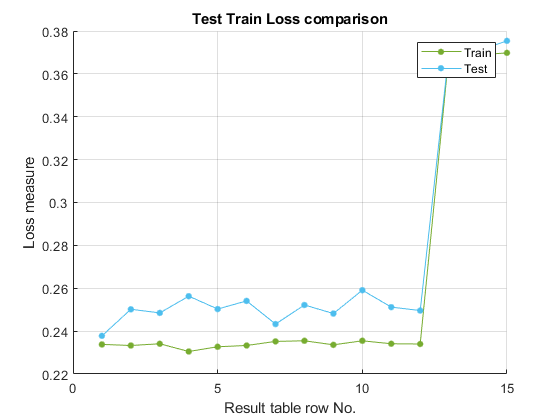

results.plotLossTestTrainComparison("Test Train Loss comparison")

results.resultsTable

    distributionName    smootherType    Width     numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ____________    ______    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'kernel'}       {'triangle'}       0.1            1                0.2338         0.2378           0.76          0.7615        0.7729      0.7672       3200         36.813   
       {'kernel'}       {'triangle'}      

ans = 15×12 table
    distributionName    smootherType    Width     numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ____________    ______    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'kernel'}       {'triangle'}       0.1            1                0.2338         0.2378           0.76          0.7615        0.7729      0.7672       3200         36.813   
       {'kernel'}       

#### Normal Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalNormalSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesNormalSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: 2.0000 DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 1560 entries out of 3200. 48.7500 pct
	Training loss: 0.48. Test Loss: 0.48
	Precision: 0.5180 Recall: 0.5711 Accuracy: 0.5125 F1: 0.5433
Test run HoldRunCount: 1 of 2,Width: 2.0000 DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 1477 entries out of 3200. 46.1563 pct
	Training loss: 0.47. Test Loss: 0.46
	Precision: 0.5

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 13268.3906

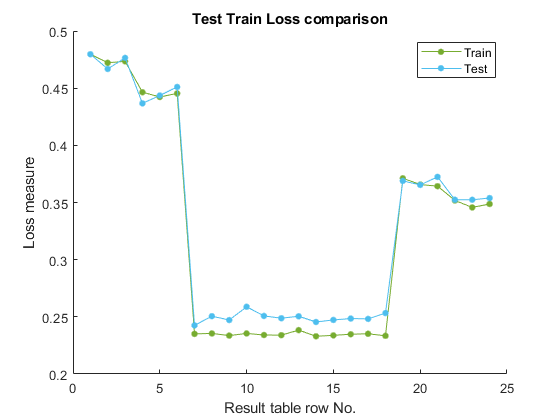

results.plotLossTestTrainComparison("Test Train Loss comparison")

#### Epanechnikov Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalEpanechnikovSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesEpanechikovSmootherSearch.csv");
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);
results.plotLossTestTrainComparison("Test Train Loss comparison")
results.resultsTable

#### Box Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalBoxSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesBoxSmootherSearch.csv");
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);
results.plotLossTestTrainComparison("Test Train Loss comparison")
results.resultsTable